clear all, close all, clc

## Prob EM2

Let,

syms P_1 P_2
P_1 = P_1;              % probability of battery 1 failing
P_2 = P_1;              % ...2 failing; and they are identical

Given,

P_1U2 = 0.005;              % probability for failing at-least one battery
P_1C2 = 0.001;              % ...failing of failing  both

We know, $P\left(B_1 +B_2 \right)=P\left(B_1 \right)+P\left(B_2 \right)-P\left(B_1 B_2 \right)$ 

Therefrom,

eqn = P_1U2 == P_1 + P_2 - P_1C2

$$eqn = \frac{1}{200}=2\,P_{1}-\frac{1}{1000}$$

Solving the equatin, we get the 

sol = solve(eqn, P_1);
P_1 = double(sol)

P_1 = 0.0030

(Ans)

**(b)**


$$P\left(1|2\right)=\frac{P\left(1\cap 2\right)}{P\left(2\right)}$$


P_2 = P_1;
P_1_2 = P_1C2/ P_2           % probab' of failing 1, given 2

P_1_2 = 0.3333

**(c)**

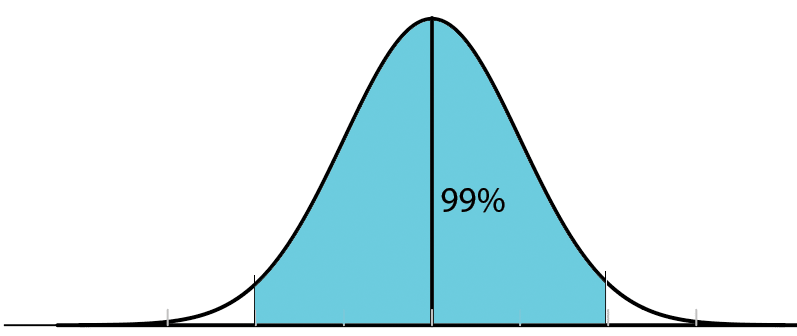

alf = 0.99;             % confidence
ar = (1-alf)/2 + alf;   % area for carlculating z
z = norminv(ar)         % z-value, corresponding alf

z = 2.5758

dl = z;                  % limit of z

Now, we know here,

$p\left(z\right)=P\left(\frac{\bar{x\;} -p}{\sigma_n }\right)=\alpha \;$, and $z<\delta \;$

Then, we get, $\frac{\bar{x\;} -p}{\sigma_n }<\delta$

Here, $\sigma \;=\sqrt{p\left(1-p\right)\;}$ and $\sigma_n =\frac{\;\sigma }{\sqrt{\;N}}$

Then, $\frac{\left(\bar{x\;} -p\right)\sqrt{\;N}}{\sqrt{p\left(1-p\right)\;}}<\delta \;$

N = 2750;           % no. of trials
f = 1;              % no . of fails
x_b = f/N            % average failure probab'

x_b = 3.6364e-04

so, the inequality can be rewritten-


$${\left(\bar{x} -p\right)}^2 \;N<{\;\delta \;}^2 p\left(1-p\right)$$


syms p real

ineq = (x_b - p)^2*N < dl^2 *p*(1 - p);   
sol = solve(ineq, p, 'ReturnConditions',true);     % 1 for true
sol.p(1);           % not nec'
res = sol.conditions;
res = vpa(res)

$$res = x<0.00308971054366237203642419298713\wedge 0.000042694335804325322395326194803231<x$$


$$x<0.00308971054366237203642419298713\wedge 0.000042694335804325322395326194803231<x$$


So, we get, p = ($0.000042$6,  $0.00308$)

(Ans)

## Prob EM3

Given

N = 1e3;            % no o pebbles
p = 1e-6*0.01;      % failure probability
k = 1;              % least no. of failure

Now, from engg. consideration,


$$P{\left(o>m\right)}=1-{\left(\sum_0^m \frac{\mu^k }{k!}\right)}\exp \left(-\mu \right)$$


mu = N*p                    % mean no. of failure

mu = 1.0000e-05

    k = linspace(0,k,k+1);        % vector in k
    fk = factorial(k);
A = (mu).^k ./fk;       % vector
A_S = sum(A)            % sumation term

A_S = 1.0000

Now, let's find the probability

P_l1 = 1 - A_S * exp(-mu)       % probab' of failing atleast one 

P_l1 = 5.0000e-11

(Ans)

## Prob EM4

Given

z_01 = 1.25e-7;          % 1st percentile
z_99 = 3.33e-4;

Now, we have

syms alpha beta a b
a = alpha; b = beta;        % definign symbols

Here, given

n_01 = -2.326;              % standard normal variable @ 1%
n_99 = +2.326;              % 
z_99_x = b *exp(n_99*a)        % expression i.t.o a & b

$$z\_99\_x = \beta \,{\mathrm{e}}^{\frac{1163\,\alpha }{500}}$$

z_01_x = b *exp(n_01*a)  

$$z\_01\_x = \beta \,{\mathrm{e}}^{-\frac{1163\,\alpha }{500}}$$

So, let's build the equation

eqn = z_01/z_99 == z_01_x/z_99_x

$$eqn = \frac{1}{2664}={\mathrm{e}}^{-\frac{1163\,\alpha }{250}}$$

sol = solve(eqn, a);
a = double(sol)

a = 1.6955

Now, let's find the median

alpha  = a;
z_99_x = eval(z_99_x)       % evaluating for alpha value

$$z\_99\_x = 6\,\sqrt{74}\,\beta$$

Then, let's find the value of beta a

eqn2 = z_99_x == z_99;
sol = solve(eqn2, b);
b = double(sol)

b = 6.4517e-06

(Ans)

That's the value of beta and the median

**(b)**

Now, we know, mean in the LN distribution

$m=\beta \;\exp \left(\frac{{\;\alpha \;}^{2\;} }{2}\right)\;$, So,

m = b *exp(a^2/2)

m = 2.7160e-05

(Ans)

## Prob EM5

**(a)**

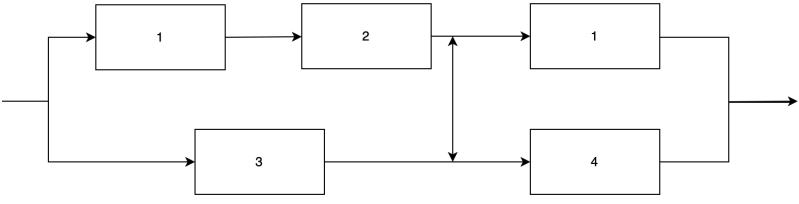

Let's take 3 as keystone component, 

syms R1 R2 R3 R4

Let's find the $R_{\textrm{sy},k}$

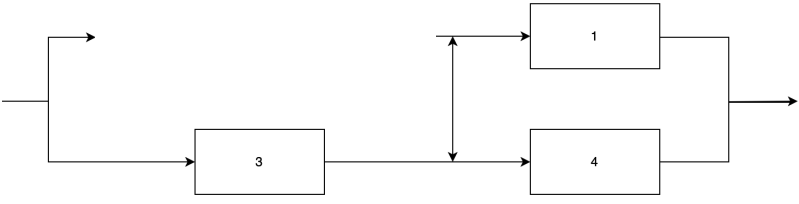

R_sy_k =  1 - (1 - R1)*(1 -R4);
R_sy_k = expand(R_sy_k)

$$R\_sy\_k = R_{1}+R_{4}-R_{1}\,R_{4}$$

Then again,$R_{\textrm{sy},\bar{k\;} }$

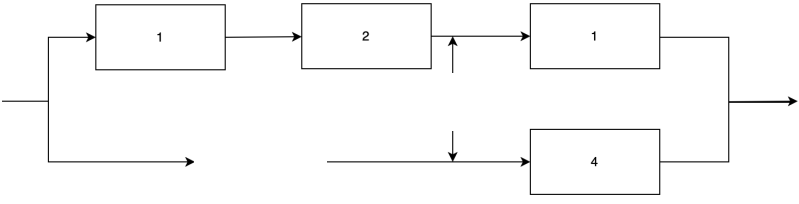

R_sy_kb = R1 * R2 *R1

$$R\_sy\_kb = {R_{1}}^{2}\,R_{2}$$

So, the system reliability-


$$\left.R_{sy} =R_k \ R{\left(sys,k\right)}+R_{\bar{k\;} } \ R\left(sys\right|\bar{k\;} \right)$$


R_sy = R3 * R_sy_k + (1 - R3)*R_sy_kb

$$R\_sy = R_{3}\,\left(R_{1}+R_{4}-R_{1}\,R_{4}\right)-{R_{1}}^{2}\,R_{2}\,\left(R_{3}-1\right)$$

(Ans)

**(b)**

Now, let's assign the follwing values

syms R t L
R1 = R; R2 = R; R3 = R; R4 = R;
R_sy = eval(R_sy)                   % expressing w.r.t R

$$R\_sy = R\,\left(2\,R-R^{2}\right)-R^{3}\,\left(R-1\right)$$

Now, 

R = exp(-L*t);
R_sy = eval(R_sy)           % evaluating w.r.t L and t

$$R\_sy = {\mathrm{e}}^{-L\,t}\,\left(2\,{\mathrm{e}}^{-L\,t}-{\mathrm{e}}^{-2\,L\,t}\right)-{\mathrm{e}}^{-3\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

Now, let's find an expression for MTTF


$$MTTF_{sy} =\int \;R_{\textrm{sy}} \left(t\right)\textrm{dt}\;\;$$


MTTF_sy = int(R_sy, t)            % hours

$$MTTF\_sy = -\frac{{\mathrm{e}}^{-4\,L\,t}\,\left(4\,{\mathrm{e}}^{2\,L\,t}-1\right)}{4\,L}$$

Now, as it is given-

L = 1e-6;                             % hazard rate; h^-1
R_sy = eval(R_sy);              % evaluating for L

Now, let's find the MTTF_sy for the limits-


$${\textrm{MTTF}}_{\textrm{sy}} =\int_0^{\infty } R_{sy} \left(t\right)dt$$


MTTF_sy = int(R_sy, t, 0, inf);            % hours
MTTF_sy = double(MTTF_sy)

MTTF_sy = 750000

(Ans)

###############################

## Functions